font_size=20;
tilt_size=16;
width = 50;         
height = 30;
SCREEN_LEFT = 0;
SCREEN_RIGHT = 0;
ADD = 0;

line_width=10;sys = tf([8 18 32],[1 6 14 24]);
P = tf([0 0 1],[1 10 20]);
%step(P)

kp = 100;
ki = 70;
kd = 10;
G1 = pid(10);
G2i = pid(0,10,0);
G2 = pid(10,60);
G2d = pid(0,0,5);
G3 = pid(10,0,10);
G4 = pid(900,310,35);
T1 = feedback(G1*P,1);
T2 = feedback(G2*P,1);
T2i = feedback(G2i*P,1);
T2d = feedback(G2d*P,1);
T3 = feedback(G3*P,1);
T4 = feedback(G4*P,1);
t = 0:0.01:5;

fig=figure(1)

fig =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [2280 918 560 420]
       Units: 'pixels'

  Show all properties


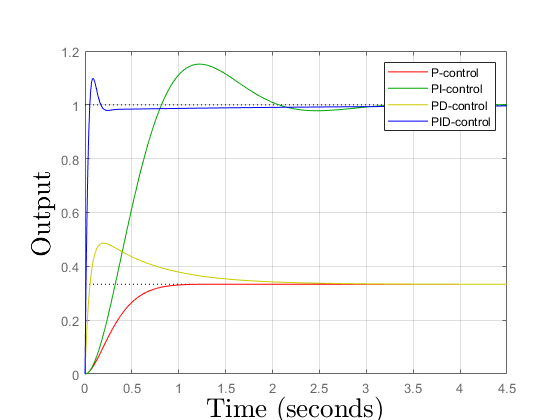

clf(fig);

step(T1,'r',T2,'g',T3,'y',T4,'b',t)
box on
title(' ')
hold on
xlim([0 4.5])
legend('P-control','PI-control','PD-control','PID-control')
xlabel('Time','Interpreter','latex','FontSize',font_size)
ylabel('Output','Interpreter','latex','FontSize',font_size)
grid on